# Seasonal soil temperature

We are interested in the pattern each year and record a clear break between early and late summer. To avoid how the transition may be different between each year, I will ignore the middle months like July. But before making this decision, lets look at a few years. The plotting commands will be within this notebook, so it will be selfcontained

clear all
close all

We have two data sources, over different times. One is a Daily and the other is an hourly take. Since, we do not need hourly resolution, I will use the pre-existing daily average data. 

txtname = 'UK_synthesized_soil.txt';
txtsaving = 'UK_synthesized_ActiveLayer_data.txt';
matsaving = 'UK_ActiveLayer.mat';
workdir   = '/Users/cansu/Documents/Polybox_ETH/Permafrost/Upper Kuparuk River Basin Alaska_river/data/';
workdirERRA = '/Users/cansu/Documents/GitHub/Permafrost_ERRA/Permafrost_ERRA/datERRA/UK';
workdir_s_ex = '/Users/cansu/Documents/Polybox_ETH/Permafrost/Upper Kuparuk River Basin Alaska_river/data/soil data/resource_map_doi_10_18739_A29P2W70H/data';
workdir_s = '/Users/cansu/Documents/Polybox_ETH/Permafrost/Upper Kuparuk River Basin Alaska_river/data/soil data/';
filename_d = 'UpperKuparuk_Historical_Discharge_1993_2018_2018jul17.csv';
filename_s_uk = 'uk1994_2010td_simple.csv';
writetables = false;
makefigs = true;
printfig  = false;

 cd(workdir_s_ex)
%% Set up the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 13);

% Specify range and delimiter
opts.DataLines = [1, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["DateTimeAST", "CmDepthSoilTemperaturedegreesC", "CmDepthSoilTemperaturedegreesC1", ...
    "CmDepthSoilTemperaturedegreesC2", "CmDepthSoilTemperaturedegreesC3", "CmDepthSoilTemperaturedegreesC4",...
    "CmDepthSoilTemperaturedegreesC5", "CmDepthSoilTemperaturedegreesC6", "CmDepthSoilTemperaturedegreesC7",...
    "CmDepthSoilTemperaturedegreesC8", "CmDepthSoilTemperaturedegreesC9", "CmDepthSoilTemperaturedegreesC10", ...
    "CmDepthSoilTemperaturedegreesC11"];
opts.VariableTypes = ["datetime", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, "DateTimeAST", "InputFormat", "MM/dd/yyyy HH:mm");

% Import the data
M_ = readtable(filename_s_uk, opts);
%MANUAL: I realized the first line is error so lets delete that
M_(1,:) = [];
%MANUEL: Some dates MAY not read by Matlab, so lets add those days
%back in
missingdate = isnan(decyear(M_.DateTimeAST));
missingdate_index = find(missingdate);
if length(missingdate_index)>1
    for i = 1:length(missingdate_index)
        j = missingdate_index(i);                         %index of the missing value in M_
        dtt = M_.DateTimeAST(j-1)-M_.DateTimeAST(j-2);  %time step from the previous times
        M_.DateTimeAST(j) = M_.DateTimeAST(j-1)+dtt;    %fill in the missing days
        %TEST: if there is a date in the following point, does it match
        %our dt stepping algorithm?
        if j+1~= missingdate_index(i+1)                   %is the next i index the same as the missing index?
            if M_.DateTimeAST(j) + dtt ~= M_.DateTimeAST(i+1)
                error('STOP: missing data algorithm failed')
            end
        end
        dttold = dtt;
        if dttold ~= dtt
            error('dtt changed')
        end
    end
end

[trash_, index_trash] = unique(M_.DateTimeAST,'rows');               %take unique dates, but notice that trash_ is a single column
M_trash = M_(index_trash,:);                                           %so we take all the rows that are in the table
missingdate = isnan(decyear(M_trash.DateTimeAST));
missingdate_index = find(missingdate);
if missingdate_index>0
    M_trash(missingdate_index,:) = [];          %if data is still missing, remove row
end
M = M_trash;
Temp_depth = table2array(M(:,2:end));
Temp_depth(Temp_depth > 50) = NaN;                                              %remove bad data

Now Lets plot the data

t_     = decyear(M.DateTimeAST);
t_temperature  = M.DateTimeAST;

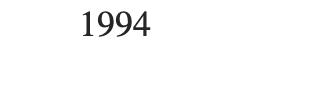


if makefigs
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%FIGURES%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% set printing options
str       = {'t_TempDepth' };
format    = '-dpng';
resl      = '-r200';
rend      = '-opengl';




% prepare formating options
HA = {'HorizontalAlignment','left','center','right'};
VA = {'VerticalAlignment','bottom','middle','top'};
UN = {'Units','Normalized','Inches'};
TX = {'Interpreter','Latex'};
TL = {'TickLabelInterpreter','Latex'};
LW = {'LineWidth',1,1.25,1.5,2};
FS = {'FontSize',10,15,18,21,24};
MS = {'MarkerSize',6,8,12};
LS = {'LineStyle','-','--','-.',':'};
% LC = {'Color',color};


%Plotting profiles
axh = 5;
axw = 4*axh;
ahs = 0.15;
avs = 0.15;
axb = 0.7;
axt = 0.5;
axl = 0.8;
axr = 0.5;
cbh = axh; cbw = 0.2; ht = 0.05;
fh = axb + 1*axh + 1*avs + 1*ht + axt ;
fw = axl  + axw + ahs + cbw + axr;




f1 = figure;
set(f1,'Units','Inches','Position',[0.7 12 fw fh]);
set(f1,'PaperPosition',[0 0 fw*2.2 fh*2.2],'PaperSize',[fw fh]);
set(f1,'Color','w','InvertHardcopy','off', 'MenuBar','none');
set(f1,'Resize','off','Toolbar','none');
ax = axes('Units','Inches','position',[axl axb axw axh]);


plot(t_,Temp_depth)
xlabel('t',TX{:},FS{[1,4]},UN{[1,3]},'Position',[axw/2+ahs/2,-axb/2]);
ylabel('Temperature [$^{\circ}$C]',TX{:},FS{[1,4]},UN{[1,3]},'Position',[-axl/2,axh/2]);
set(gca,'XLim',[min(t_),max(t_)],'Ylim',[min(min(Temp_depth)), max(max(Temp_depth))],TL{:},FS{[1,4]});


%Saving Figures
if printfig
  cd(workdir_s_ex);
  figname   = char(strcat(str(1)));
  print(f1,format,resl,rend,figname,'-loose');
end

end

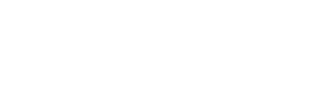

% I want to also include air temperature so lets get that data too
workdir_m = '/Users/cansu/Documents/Polybox_ETH/Permafrost/Upper Kuparuk River Basin Alaska_river/data/metereological data/';
filename_m_uk = 'uk1994_2018m_simple.csv';

cd(workdir_m)
%% Set up the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 19);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["DateTimeAST", "MAirTemperaturedegC", "MAirTemperaturedegC1", "MAirTemperaturedegC2", "MAirTemperaturedegC3", "MRelativeHumidity", "MRelativeHumidity1", "MRelativeHumidity2", "MRelativeHumidity3", "MWindSpeedms", "MWindSpeedms1", "MWindSpeedms2", "MWindSpeedms3", "MWindDirectiondegrees", "Rainfallmm", "StationPressuremb", "SnowDepthcm", "VarName18", "VarName19"];
opts.VariableTypes = ["datetime", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "string", "string"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, ["VarName18", "VarName19"], "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["VarName18", "VarName19"], "EmptyFieldRule", "auto");
opts = setvaropts(opts, "DateTimeAST", "InputFormat", "MM/dd/yyyy HH:mm");

% Import the data
Mp_ = readtable(filename_m_uk, opts);

%MANUEL: Some dates are actually not read by Matlab, so lets add those days
%back in
missingdate = isnan(decyear(Mp_.DateTimeAST));
missingdate_index = find(missingdate);
for i = 1:length(missingdate_index)
    j = missingdate_index(i);                         %index of the missing value in Mp_
    dtt = Mp_.DateTimeAST(j-1)-Mp_.DateTimeAST(j-2);  %time step from the previous times
    Mp_.DateTimeAST(j) = Mp_.DateTimeAST(j-1)+dtt;    %fill in the missing days
    %TEST: if there is a date in the following point, does it match
    %our dt stepping algorithm?
    if j+1~= missingdate_index(i+1)                   %is the next i index the same as the missing index?
        if Mp_.DateTimeAST(j) + dtt ~= Mp_.DateTimeAST(i+1)
                error('STOP: missing data algorithm failed')
        end
    end
    dttold = dtt;
    if dttold ~= dtt
        error('dtt changed')
    end
end


[trash_ index_trash] = unique(Mp_.DateTimeAST,'rows');               %take the date data
Mp_trash = Mp_(index_trash,:);
Mp = rmmissing(Mp_trash);

%remove bad data
Mp.MAirTemperaturedegC(ismember(Mp.MAirTemperaturedegC,7777)) = NaN;
Mp.MAirTemperaturedegC(ismember(Mp.MAirTemperaturedegC,6999)) = NaN;


%This is incase time is not continuous
tp_     = Mp.DateTimeAST;
tp_cont = tp_(1):minutes(60):tp_(end);
index_timep_o = find(ismember(tp_,tp_cont)); %%% index of the original data
index_timep_s = find(ismember(tp_cont,tp_)); %%% index of the continuous data


%export air temperature
AT_ = Mp.MAirTemperaturedegC(index_timep_o);
AT_cont = nan(size(tp_cont));
AT_cont(index_timep_s) = AT_;

%Convert hourly data to daily data
temp_hourly = AT_cont;
t_hourly = tp_cont;
t_daily = dateshift(t_hourly, 'start', 'day');
temp_daily = splitapply(@nanmean, temp_hourly, findgroups(t_daily))';
t_daily = unique(t_daily);
plot(t_daily, temp_daily);

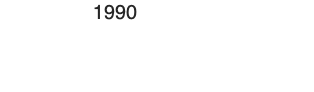


%We want days as number of days, not dates
num_days = numel(t_daily);
t_no = 1:num_days;
t_no = t_no';



%plot
plot(decyear(t_daily), temp_daily);
hold on 
plot(t_,Temp_depth)

cd('/Users/cansu/Documents/GitHub/Permafrost_ERRA/datERRA/UK_years')
if writetables
    save('AirTemp.mat','t_daily','temp_daily')
end

t_m = month(M.DateTimeAST);
t_d = day(M.DateTimeAST);
t_y = year(M.DateTimeAST);

data = [t_m,t_d,Temp_depth];
A = table(data);
A = splitvars(A,"data","NewVariableNames",["month","day","T5","T10","T15","T20","T25","T30","T35","T40","T45","T50","T55","T60"]);
depths = ["T5","T10","T15","T20","T25","T30","T35","T40","T45","T50","T55","T60"];
dailyMeanT = groupsummary(A,["month","day"],{"mean"},["T5","T10","T15","T20","T25","T30","T35","T40","T45","T50","T55","T60"]);
dailyMaxT = groupsummary(A,["month","day"],{"max"},["T5","T10","T15","T20","T25","T30","T35","T40","T45","T50","T55","T60"]);
dailyMinT = groupsummary(A,["month","day"],{"min"},["T5","T10","T15","T20","T25","T30","T35","T40","T45","T50","T55","T60"]);
dailystdT = groupsummary(A,["month","day"],{"std"},["T5","T10","T15","T20","T25","T30","T35","T40","T45","T50","T55","T60"]);

MD = datetime(ones(size(dailyMeanT,1),1),dailyMeanT.month,dailyMeanT.day);
dailyMean = table2array(dailyMeanT(:,4:end));
dailystd = table2array(dailystdT(:,4:end));

if makefigs
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%FIGURES%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% set printing options
str       = {'t_TempDepth_averaged' };
format    = '-dpng';
resl      = '-r200';
rend      = '-opengl';




% prepare formating options
HA = {'HorizontalAlignment','left','center','right'};
VA = {'VerticalAlignment','bottom','middle','top'};
UN = {'Units','Normalized','Inches'};
TX = {'Interpreter','Latex'};
TL = {'TickLabelInterpreter','Latex'};
LW = {'LineWidth',1,1.25,1.5,2};
FS = {'FontSize',10,15,18,21,24};
MS = {'MarkerSize',6,8,12};
LS = {'LineStyle','-','--','-.',':'};
% LC = {'Color',color};


%Plotting profiles
axh = 5;
axw = 4*axh;
ahs = 0.15;
avs = 0.15;
axb = 0.7;
axt = 0.5;
axl = 0.8;
axr = 0.5;
cbh = axh; cbw = 0.2; ht = 0.05;
fh = axb + 1*axh + 1*avs + 1*ht + axt ;
fw = axl  + axw + ahs + cbw + axr;




f1 = figure;
set(f1,'Units','Inches','Position',[0.7 12 fw fh]);
set(f1,'PaperPosition',[0 0 fw*2.2 fh*2.2],'PaperSize',[fw fh]);
set(f1,'Color','w','InvertHardcopy','off', 'MenuBar','none');
set(f1,'Resize','off','Toolbar','none');
ax = axes('Units','Inches','position',[axl axb axw axh]);


plot(MD,dailyMean)
xlabel('t',TX{:},FS{[1,4]},UN{[1,3]},'Position',[axw/2+ahs/2,-axb/2]);
ylabel('Temperature [$^{\circ}$C]',TX{:},FS{[1,4]},UN{[1,3]},'Position',[-axl/2,axh/2]);
set(gca,'XLim',[min(MD),max(MD)],'Ylim',[min(min(dailyMean)), max(max(dailyMean))],TL{:},FS{[1,4]});

legend("T5","T10","T15","T20","T25","T30","T35","T40","T45","T50","T55","T60",FS{[1,3]},TX{[1,2]});

%Saving Figures
if printfig
  cd(workdir_s_ex);
  figname   = char(strcat(str(1)));
  print(f1,format,resl,rend,figname,'-loose');
end
end

if makefigs
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%FIGURES%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% set printing options
str       = {'t_TempDepth_std' };
format    = '-dpng';
resl      = '-r200';
rend      = '-opengl';




% prepare formating options
HA = {'HorizontalAlignment','left','center','right'};
VA = {'VerticalAlignment','bottom','middle','top'};
UN = {'Units','Normalized','Inches'};
TX = {'Interpreter','Latex'};
TL = {'TickLabelInterpreter','Latex'};
LW = {'LineWidth',1,1.25,1.5,2};
FS = {'FontSize',10,15,18,21,24};
MS = {'MarkerSize',6,8,12};
LS = {'LineStyle','-','--','-.',':'};
LL = {'Location','northwest','northeast','southwest','southeast'};
% LC = {'Color',color};


%Plotting profiles
axh = 5;
axw = 4*axh;
ahs = 0.15;
avs = 0.15;
axb = 0.7;
axt = 0.5;
axl = 0.8;
axr = 0.5;
cbh = axh; cbw = 0.2; ht = 0.05;
fh = axb + 1*axh + 1*avs + 1*ht + axt ;
fw = axl  + axw + ahs + cbw + axr;




f1 = figure;
set(f1,'Units','Inches','Position',[0.7 12 fw fh]);
set(f1,'PaperPosition',[0 0 fw*2.2 fh*2.2],'PaperSize',[fw fh]);
set(f1,'Color','w','InvertHardcopy','off', 'MenuBar','none');
set(f1,'Resize','off','Toolbar','none');
ax = axes('Units','Inches','position',[axl axb axw axh]);


plot(MD,dailystd)
xlabel('t',TX{:},FS{[1,4]},UN{[1,3]},'Position',[axw/2+ahs/2,-axb/2]);
ylabel('Temperature [$^{\circ}$C]',TX{:},FS{[1,4]},UN{[1,3]},'Position',[-axl/2,axh/2]);
set(gca,'XLim',[min(MD),max(MD)],'Ylim',[min(min(dailystd)), max(max(dailystd))],TL{:},FS{[1,4]});

legend("T5","T10","T15","T20","T25","T30","T35","T40","T45","T50","T55","T60",FS{[1,3]},TX{[1,2]});

%Saving Figures
if printfig
  cd(workdir_s_ex);
  figname   = char(strcat(str(1)));
  print(f1,format,resl,rend,figname,'-loose');
end
end

# Model Active Layer Thickness Given above data

% %Lets find a model that calculates Thermal diffusion (K) for all depths and
% %temperatures
% depths_NO = 5:5:60; 
% time1 = t_;
% dt = time1(2:end)-time1(1:end-1);
% dy = depths_NO(2:end)-depths_NO(1:end-1);
% %approximate K
% K = nan(numel(time1),numel(depths_NO));
% for j = 1:numel(time1)-1
%     for i = 2:numel(Temp_depth(1,:))-1
%         d2T = Temp_depth(j,i+1)-2.*Temp_depth(j,i) + Temp_depth(j,i-1);
%         dT  = Temp_depth(j+1,i) - Temp_depth(j,i);
% 
%         K(j,i) = [dT./d2T*dy(i)^2/dt(j)];
%     end
% end
% K(abs(K)>10000)=nan;
% KK = nanmean(nanmean(abs(K)))
% %using data calculate the 
% for j = 2:numel(time1)
%     for j = 2:numel(depths_NO)-1
%         d2T = Temp_depth(j,i+1)-2.*Temp_depth(j,i) + Temp_depth(j,i-1);
%         
%        Temp_depth_sim(j,i) = KK.* dt(j)./dy(i).^2.*d2T + Temp_depth(j,i);
%     end
% end

% j = 1;
% trueT = Temp_depth(253,:);
% simT = Temp_depth(252,:) + (Temp_depth(252,1)-Temp_depth(252,:)).*exp((depths_NO(1)-depths_NO)/KK);

# Active Layer Thickness (on average)

The data I gathered is from GTN-P and the sites are Imnavait Creek and Toolik, which are not exactly at UK but close. [http://gtnpdatabase.org/activelayers](http://gtnpdatabase.org/activelayers)


close all

workdir_s_ex = '/Users/cansu/Documents/Polybox_ETH/Permafrost/Upper Kuparuk River Basin Alaska_river/data/soil data/Activelayers-17-230-231_with_timeseries';
filename_ac = {'Activelayer_17-Imnavait_1km-Dataset_281-Sporadic-Unknown-Active_Layer_Thickness_grid_transect-Mechanical_Probing.timeserie.csv',...
    'Activelayer_18-Toolik_1km-Dataset_282-Sporadic-Unknown-Active_Layer_Thickness_grid_transect-Mechanical_Probing.timeserie.csv',...
    'Activelayer_229-Toolik_MAT-Dataset_1509-Sporadic-As_Needed-Active_Layer_Thickness_grid_transect-Mechanical_Probing.timeserie.csv',...
    'Activelayer_230-Imnavait_Creek_MAT-Dataset_1510-Sporadic-As_Needed-Active_Layer_Thickness_grid_transect-Mechanical_Probing.timeserie.csv'};
opst_size = [39,38,34,40]
years_available = 1995:2020;
meanActiveLayer_year = nan(size(years_available));
cd(workdir_s_ex)
if makefigs
str       = {'ActiveLayerThickness' };
f2 = figure;
set(f2,'Units','Inches','Position',[0.7 12 fw fh]);
set(f2,'PaperPosition',[0 0 fw*2.2 fh*2.2],'PaperSize',[fw fh]);
set(f2,'Color','w','InvertHardcopy','off', 'MenuBar','none');
set(f2,'Resize','off','Toolbar','none');
ax = axes('Units','Inches','position',[axl axb axw axh]);
end




for j = 1:numel(filename_ac)

opts = delimitedTextImportOptions("NumVariables", opst_size(j));
opts2 = opts;
% Specify range and delimiter
opts.DataLines = [1, Inf];
opts2.DataLines = [1, 1];
opts.Delimiter = ",";
opts2.Delimiter = ",";

% Specify column names and types
C1    = cell(1, opst_size(j));
C2    = cell(1, opst_size(j));
C1(:) = {'double'};
C2(:) = {'datetime'};
opts.VariableTypes = C1; 
opts2.VariableTypes = C2;

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";
opts2.ExtraColumnsRule = "ignore";
opts2.EmptyLineRule = "read";


% Import the data
M_ = table2array(readtable(filename_ac{j}, opts));
M_(:,1:2) = [];
M_(1,:) = [];
M_(M_<-200) = NaN;
Mdates_ = table2array(readtable(filename_ac{j}, opts2));
Mdates_(1:2) = [];

years_AL = year(Mdates_);
months_AL = month(Mdates_);
meanActiveLayer = nanmean(M_,1);
%come back to fix this
if j == 1
    times_AL_imnavait_dates = Mdates_;
times_AL_imnavait     = decyear(Mdates_);
Imnavait_1km_all      = meanActiveLayer;
end


for i = 1:numel(years_available)
    meanActiveLayer_year(j,i) = mean(meanActiveLayer(months_AL==8&years_AL == years_available(i)));
end
if makefigs
hold on
plot(years_available,meanActiveLayer_year(j,:),'.','MarkerSize',35)
end

%Saving Figures

%% Clear temporary variables
clear opts opts2

end
if makefigs
xlabel('Time (August of the year)',TX{:},FS{[1,4]},UN{[1,3]},'Position',[axw/2+ahs/2,-axb/2]);
ylabel('Active Layer Thickness [cm]',TX{:},FS{[1,4]},UN{[1,3]},'Position',[-axl/2,axh/2]);
set(gca,'XLim',[min(years_available),max(years_available)],'Ylim',[min(min(meanActiveLayer_year)), max(max(meanActiveLayer_year))],TL{:},FS{[1,4]});

legend(filename_ac,FS{[1,3]},TX{[1,2]},LL{[1,4]});
end

if makefigs
plot(years_available,nanmean(meanActiveLayer_year,1),'-','LineWidth',3)
if printfig
  cd(workdir_s_ex);
  figname   = char(strcat(str(1)));
  print(f2,format,resl,rend,figname,'-loose');
end
end

# Save data

%First make a table
Imnavait_1km = meanActiveLayer_year(1,:);
Toolik_1km = meanActiveLayer_year(2,:);
Toolik_Mat = meanActiveLayer_year(3,:);
Imnavait_Mat = meanActiveLayer_year(4,:);
meanActiveLayer = nanmean(meanActiveLayer_year,1);
Mtxt = table(years_available,Imnavait_1km,Toolik_1km,...
    Imnavait_Mat,Toolik_Mat,meanActiveLayer);
if writetables ==1
    writetable(Mtxt,txtsaving,'WriteRowNames',true,'Delimiter',',');
    cd(workdirERRA)
    writetable(Mtxt,txtsaving,'WriteRowNames',true,'Delimiter',',');

    save(matsaving,'years_available','Imnavait_1km','Toolik_1km',...
    'Imnavait_Mat','Toolik_Mat','meanActiveLayer')
end

# How does Imnavit 1km compare to temperature data?

Here, what I am doing is going down the matrix that is temperature at a given depth over time and seeing when it drops below 0 degrees. 

depthAL = nan(1,numel(t_)); 
depths_NO = 5:5:60; 
for j = 1:numel(t_)
    if sum(Temp_depth(j,:)<=0)>0
        if t_m(j) < 8
        for i = 1:numel(depths_NO)
            if Temp_depth(j,i)<0
                depthAL(j) = depths_NO(i);
                break
            end
        end
        elseif t_m(j)>=8
            for i = numel(depths_NO):-1:2
                if Temp_depth(j,i)<0&&Temp_depth(j,i-1)>0
                  depthAL(j)=depths_NO(i);
                  break
                end
            end
        end
    end
end
snowfree = t_m>5&t_m<12;
warming = t_m>5&t_m<9;


if makefigs
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%FIGURES%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% set printing options
str       = {'TemperatureData_ImnavaitData_ActiveLayerThickness' };
format    = '-dpng';
resl      = '-r200';
rend      = '-opengl';




% prepare formating options
HA = {'HorizontalAlignment','left','center','right'};
VA = {'VerticalAlignment','bottom','middle','top'};
UN = {'Units','Normalized','Inches'};
TX = {'Interpreter','Latex'};
TL = {'TickLabelInterpreter','Latex'};
LW = {'LineWidth',1,1.25,1.5,2};
FS = {'FontSize',10,15,18,21,24};
MS = {'MarkerSize',6,8,12};
LS = {'LineStyle','-','--','-.',':'};
LL = {'Location','northwest','northeast','southwest','southeast'};
% LC = {'Color',color};


%Plotting profiles
axh = 5;
axw = 4*axh;
ahs = 0.15;
avs = 0.15;
axb = 0.7;
axt = 0.5;
axl = 0.8;
axr = 0.5;
cbh = axh; cbw = 0.2; ht = 0.05;
fh = axb + 1*axh + 1*avs + 1*ht + axt ;
fw = axl  + axw + ahs + cbw + axr;




f1 = figure;
set(f1,'Units','Inches','Position',[0.7 12 fw fh]);
set(f1,'PaperPosition',[0 0 fw*2.2 fh*2.2],'PaperSize',[fw fh]);
set(f1,'Color','w','InvertHardcopy','off', 'MenuBar','none');
set(f1,'Resize','off','Toolbar','none');
ax = axes('Units','Inches','position',[axl axb axw axh]);



plot(t_(warming),depthAL(warming),'.b','MarkerSize',5)
hold on
plot(times_AL_imnavait,Imnavait_1km_all,'or','MarkerSize',5)

xlabel('time',TX{:},FS{[1,4]},UN{[1,3]},'Position',[axw/2+ahs/2,-axb/2]);
ylabel('Active Layer Thickness',TX{:},FS{[1,4]},UN{[1,3]},'Position',[-axl/2,axh/2]);
set(gca,'XLim',[min(times_AL_imnavait),max(times_AL_imnavait)],'Ylim',[0, max(Imnavait_1km_all)],TL{:},FS{[1,4]});

legend("Depth of Active Layer from Temperature","Depth of Active Layer from Imnavait (5km away)",FS{[1,3]},TX{[1,2]});

%Saving Figures
if printfig
  cd(workdir_s_ex);
  figname   = char(strcat(str(1)));
  print(f1,format,resl,rend,figname,'-loose');
end
end




depthAL_trim = depthAL;
for j = 2:numel(t_)
    if depthAL(j)==depthAL(j-1)
        depthAL_trim(j) = nan;
    end
    if depthAL(j)<depthAL(j-1)
        depthAL_trim(j) = nan;
    end
end

# Modeling Active layer thickness from temperature data


for l=1:numel(years_available)
%     figure
    data_ = depthAL_trim(warming&t_y==years_available(l));
    time_ = t_(warming&t_y==years_available(l))-t_y(l);
    %remove nan spots
    time_ = time_(~isnan(data_));
    data_ = data_(~isnan(data_));
%     hold on
%     plot(time_,data_,'.')
    fitting_on_indx = data_>=10;
    Poly(l,:) = polyfit(time_(fitting_on_indx),data_(fitting_on_indx),1);
    yfit = Poly(l,1).*time_+Poly(l,2);
%     hold on;
%     plot(time_,yfit,'r-.');
end
Poly(Poly==0) = nan;
    save(matsaving,'years_available','Imnavait_1km','Toolik_1km',...
    'Imnavait_Mat','Toolik_Mat','meanActiveLayer','Poly','years_available')

I want to model the thaw front thickness with time for a given average temperature during warm season using the Stefan Solution. Then I will compare to actual data. The equation will take a form that looks like:

Z = \beta \sqrt(t \bar{T}) + \alpha

where 

\bar{T}................................................................................................... is the mean temperature during the warm season (^{\circ}C),

t ............................................................................................................ is time since first day that surface temperature is > 0^{\circ}C [s],

\alpha ...................................................................................................is the initial active layer thickness (0 in our case),

\beta = \sqrt( \frac{2n\lambda }{ \rho w L},

where 

n ...........................................................................................................is the dimensionless ratio of seasonal ground- surface and air temperature (Shur and Slav-in-Borouski, 1993),

\lambda................................................................................................. is the thermal conductivity of the thawes soil [W/(mC)],

\rho ........................................................................................................is soil density (kg/m^3),

w.............................................................................................................is the relative water content,

L............................................................................................................. is the latent heat of fusion (J/kg)

Instead of looking up each of these parameters, I will match from data

%lets break up each year and calculate this differently. ONE BIG ASSUMPTION
%is the onset of thaw is based on data from a different place. 
years_available_temperature = unique(t_y);
ll = 0;
ThawThickness = nan(size(t_temperature));
Z_svd = [];
sqrt_t_svd = [];
for i = 1:numel(years_available_temperature)
    %Temperature data
    currentyear = years_available_temperature(i);
    indexingcurrent = t_y == currentyear;
    time_ = t_temperature(indexingcurrent);
    surfacetemperature = Temp_depth(indexingcurrent,1);
    surfacetemperature2 = Temp_depth(indexingcurrent,2);
    indx_NON0day = surfacetemperature>0 | surfacetemperature2 >0;
    NON0day = time_(indx_NON0day);
    modeled(i) = 0; %is the year based on data?
    if numel(NON0day)==0
        modeled(i) = 1; %the results will need to be modeled
        continue;
    end
    frstNON0day = NON0day(1);
    meanT_NON0days = nanmean(surfacetemperature(indx_NON0day));
    %active layer thickness data
    %determine what data is available for Imanvit 
    indexingcurrent = year(times_AL_imnavait_dates) == currentyear;
    dates_available = times_AL_imnavait_dates(indexingcurrent);
    ALT_available = [0 Imnavait_1km_all(indexingcurrent)]; %we know that thaw depth is 0 at start of T>0
    if ~isempty(dates_available)
        disp('data match')
        
        model_time = [0; abs(etime(datevec(frstNON0day),datevec(dates_available)))]; %seconds since non-zero temperature
        if numel(model_time)>1
            ll = ll+1;
            figure 
            sqrt_t = sqrt(model_time);
            Z = ALT_available;
            plot(sqrt_t,Z)
            beta_alpha(ll,:) = polyfit(sqrt_t,Z,1);
            sqrt_t_svd = [sqrt_t_svd; sqrt_t];
            Z_svd = [Z_svd Z];
     
            hold on;
            test_time_seconds = 0:60*60*24:model_time(end);
            sqrt_test_seconds = sqrt(test_time_seconds);
            Zfit = beta_alpha(ll,1).*sqrt_test_seconds+beta_alpha(ll,2);
            plot(sqrt(test_time_seconds),Zfit,'r-.');

            %%%%%%%%%%%%%%%%%%
            %%%%% we want the date when thawing begins
            frstNON0day_svd(ll) = frstNON0day;
            lstdataday_svd(ll) = dates_available(end);
            tindex = [find(t_temperature ==frstNON0day) find(t_temperature ==lstdataday_svd(ll))];
            ThawThickness(tindex(1):tindex(end)) = Zfit;
        end
    end
end
%find the average day that T goes above 0
frac_days = day(frstNON0day_svd,'dayofyear');
avg_frac_day = mean(frac_days);
avg_date0 = days(floor(avg_frac_day)-1); 



% average thawing process
beta_alpha_av = polyfit(sqrt_t_svd,Z_svd,1);
figure
test_time_seconds = 0:60*60*24:model_time(end);
sqrt_test_seconds = sqrt(test_time_seconds);
Zfit = beta_alpha_av(1).*sqrt_test_seconds+beta_alpha_av(2);
plot(sqrt_t_svd,Z_svd,'.r','MarkerSize',35)
hold on;
plot(sqrt(test_time_seconds),Zfit,'b-');


%IF a year does not have thaw depth, then we can model it from previous
%years
for i = 1:numel(years_available_temperature)
    if modeled(i) == 1
        currentyear = years_available_temperature(i);
        indexingcurrent = t_y == currentyear;
        time_ = t_temperature(indexingcurrent);
        frstNON0day = datetime(currentyear,1,1) + days(floor(avg_frac_day)-1);
        lstdataday = datetime(currentyear,8,15);
        model_time = [0; abs(etime(datevec(frstNON0day),datevec(lstdataday)))];
        test_time_seconds = model_time(1):60*60*24:model_time(end);
        sqrt_test_seconds = sqrt(test_time_seconds);
        Zfit = beta_alpha_av(1).*sqrt_test_seconds+beta_alpha_av(2);

        frstNON0day_svd(i) = frstNON0day;
        lstdataday_svd(i) = lstdataday(end);
        tindex = [find(t_temperature ==frstNON0day) find(t_temperature ==lstdataday_svd(i))];
        ThawThickness(tindex(1):tindex(end)) = Zfit;
    end
end

figure
 plot(t_temperature,ThawThickness)   
   cd(workdir_s)
save('ThawModel.mat','t_temperature','ThawThickness','beta_alpha')

% Find average thickness for each month
monthAvg = zeros(1, 12);
for m = 1:12
    idx = month(t_temperature) == m;
    monthAvg(m) = nanmean(ThawThickness(idx));
end
 cd(workdir_s)
save('ThawModel.mat','t_temperature','ThawThickness','beta_alpha','monthAvg')

%I need to model until 2017 for Upper Kuparuk, so lets alter this
%code to fill in the missing years
% years_missing = 2011:2017;

t_temperature_extended = t_temperature(1):days(1):datetime('2017-12-30');
t_y_extended = year(t_temperature_extended);
years_available_temperature = unique(t_y_extended);
ThawThickness_extended = nan(size(t_temperature_extended));
ThawThickness_extended(1:numel(ThawThickness))= ThawThickness;
modeled_extended = ones(size(years_available_temperature));
modeled_extended(1:numel(modeled)) = modeled;
for i = 1:numel(years_available_temperature)
    if modeled_extended(i) == 1
        currentyear = years_available_temperature(i);
        indexingcurrent = t_y_extended == currentyear;
        time_ = t_temperature_extended(indexingcurrent);
        frstNON0day = datetime(currentyear,1,1) + days(floor(avg_frac_day)-1);
        lstdataday = datetime(currentyear,8,15);
        model_time = [0; abs(etime(datevec(frstNON0day),datevec(lstdataday)))];
        test_time_seconds = model_time(1):60*60*24:model_time(end);
        sqrt_test_seconds = sqrt(test_time_seconds);
        Zfit = beta_alpha_av(1).*sqrt_test_seconds+beta_alpha_av(2);

        frstNON0day_svd(i) = frstNON0day;
        lstdataday_svd(i) = lstdataday(end);
        tindex = [find(t_temperature_extended ==frstNON0day) find(t_temperature_extended ==lstdataday_svd(i))];
        ThawThickness_extended(tindex(1):tindex(end)) = Zfit;
    end
end
figure
 plot(t_temperature_extended,ThawThickness_extended) 

  
   cd(workdir_s)
save('ThawModel_t_temp_extended.mat','t_temperature_extended','ThawThickness','t_temperature_extended','ThawThickness_extended','beta_alpha')

%What is the average thickness of the thaw depth with each month
% Find average thickness for each month
monthAvg = zeros(1, 12);
for m = 1:12
    idx = month(t_temperature_extended) == m;
    monthAvg(m) = mean(ThawThickness_extended(idx));
end

Modeling rate of layer thickenning with initial discharge

    workdirERRA = '/Users/cansu/Documents/GitHub/Permafrost_ERRA/datERRA/UK';
    cd(workdirERRA)
    discharge = load("discharge.mat",'Q','short_t_cont_num','years','months');
    Q = discharge.Q;
    t_q = discharge.short_t_cont_num;
    years_dis = discharge.years;
    months_dis = discharge.months;
    max_Q= nan(1,numel(years_available));
for l = 1:numel(years_available)
    index = t_q>years_available(l)&t_q<years_available(l)+0.47;
    if sum(index)>0
       max_Q(l) = max(Q(index));
    end
end


if makefigs
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%FIGURES%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% set printing options
str       = {'RateofActiveLayer_MaxDischarge' };
format    = '-dpng';
resl      = '-r200';
rend      = '-opengl';




% prepare formating options
HA = {'HorizontalAlignment','left','center','right'};
VA = {'VerticalAlignment','bottom','middle','top'};
UN = {'Units','Normalized','Inches'};
TX = {'Interpreter','Latex'};
TL = {'TickLabelInterpreter','Latex'};
LW = {'LineWidth',1,1.25,1.5,2};
FS = {'FontSize',10,15,18,21,24};
MS = {'MarkerSize',6,8,12};
LS = {'LineStyle','-','--','-.',':'};
LL = {'Location','northwest','northeast','southwest','southeast'};
% LC = {'Color',color};


%Plotting profiles
axh = 5;
axw = axh;
ahs = 0.15;
avs = 0.15;
axb = 0.7;
axt = 0.5;
axl = 0.8;
axr = 0.5;
cbh = axh; cbw = 0.2; ht = 0.05;
fh = axb + 1*axh + 1*avs + 1*ht + axt ;
fw = axl  + axw + ahs + cbw + axr;




f1 = figure;
set(f1,'Units','Inches','Position',[0.7 12 fw fh]);
set(f1,'PaperPosition',[0 0 fw*2.2 fh*2.2],'PaperSize',[fw fh]);
set(f1,'Color','w','InvertHardcopy','off', 'MenuBar','none');
set(f1,'Resize','off','Toolbar','none');
ax = axes('Units','Inches','position',[axl axb axw axh]);


plot(Poly(:,1),max_Q,'.','MarkerSize', 35)
xlabel('Rate of Active Layer Thicknening [cm/time]',TX{:},FS{[1,4]},UN{[1,3]},'Position',[axw/2+ahs/2,-axb/2]);
ylabel('Maximum Discharge in early summer',TX{:},FS{[1,4]},UN{[1,3]},'Position',[-axl/2,axh/2]);
set(gca,'XLim',[min(Poly(:,1)),max(Poly(:,1))],'Ylim',[nanmin(max_Q), nanmax(max_Q)],TL{:},FS{[1,4]});

%Saving Figures
if printfig
  cd(workdir_s_ex);
  figname   = char(strcat(str(1)));
  print(f1,format,resl,rend,figname,'-loose');
end
end









